**1)** Importamos los datos que ya pasamos por HOBBOware 

A=readtimetable("./01_datos/csv/Avicenia_2020_2021/Avicenias_SerieAnual.csv");

B=readtimetable("./01_datos/csv/Franja_2020_2021/Franja_Cel_todos_2021_2021.csv");

C=readtimetable("01_datos\csv\Cuenca_adentro_2020_2021\Cuenca_Adentro_todos_2020_2021.csv");

D=readtimetable("01_datos\csv\Peten_2020_2021\Petén_todos_2020_2021.csv");

patm=readtimetable("01_datos\csv\Cuenca__Afuera_oct_2022.csv");

**2) **Visualizamos los datos con un plot para conocer como van los datos 

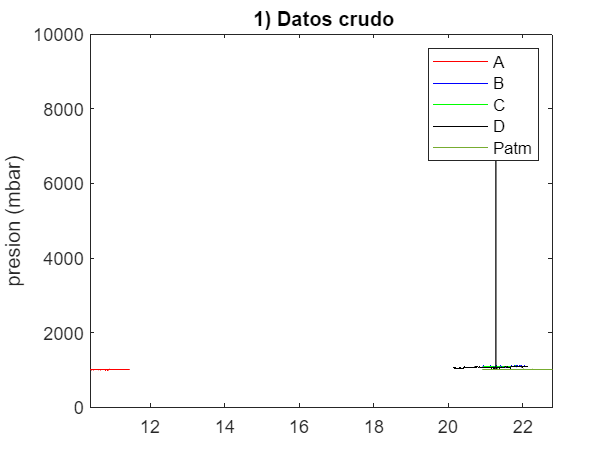

figure()
plot(A.FechaTiempo_GMT_05_00,A.PresAbs_Mbar_LGRS_N_20158088_SENS_N_20158088_,'r')
hold on 
plot(B.FechaTiempo_GMT_06_00,B.PresAbs_Mbar_LGRS_N_20081790_duplicate_duplicate_duplicate_dupl,'b')
hold on 
plot(C.FechaTiempo_GMT_06_00,C.PresAbs_Mbar_LGRS_N_20081791_duplicate_duplicate_duplicate_dupl,'g')
hold on 
plot(D.FechaTiempo_GMT_05_00,D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_,'k')
hold on 
plot(patm.FechaTiempo_GMT_05_00,patm.PresAbs_Mbar_LGRS_N_20081788_SENS_N_20081788_)
legend("A","B","C","D","Patm")
title(" 1) Datos crudo")
ylabel("presion (mbar)")

Vemos que*** hay un error en los datos***. La fecha esta mal ajustada, entonces lo podemos reparar.

**3)** Correción de fechas. Para esto vamos a sumar el tiempo que sabemos que esta perdido para cada uno de los sitios 

%Vemos que lee el archivo mal en la fecha de todos, entonces le sumamos los 2000
y=years(2000);
%Sumamos para cada caso 
A.FechaTiempo_GMT_05_00=A.FechaTiempo_GMT_05_00+y;
C.FechaTiempo_GMT_06_00=C.FechaTiempo_GMT_06_00+y;
B.FechaTiempo_GMT_06_00=B.FechaTiempo_GMT_06_00+y;
D.FechaTiempo_GMT_05_00=D.FechaTiempo_GMT_05_00+y;
patm.FechaTiempo_GMT_05_00=patm.FechaTiempo_GMT_05_00+y;

%EN EL CASO DE A EL SENSOR TIENE UNA DESCONFIGURACIÓN DE 10 AÑOS
y=years(10);
A.FechaTiempo_GMT_05_00=A.FechaTiempo_GMT_05_00+y;

Volvemos a visualizar los datos para ver sí se hizó la correción de la fecha de forma adecuada 

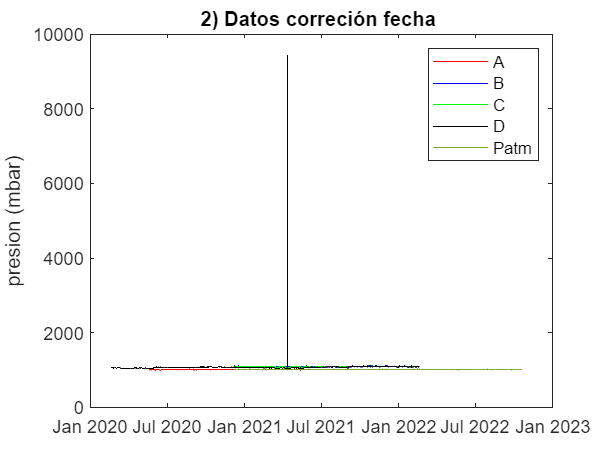

figure()
plot(A.FechaTiempo_GMT_05_00,A.PresAbs_Mbar_LGRS_N_20158088_SENS_N_20158088_,'r')
hold on 
plot(B.FechaTiempo_GMT_06_00,B.PresAbs_Mbar_LGRS_N_20081790_duplicate_duplicate_duplicate_dupl,'b')
hold on 
plot(C.FechaTiempo_GMT_06_00,C.PresAbs_Mbar_LGRS_N_20081791_duplicate_duplicate_duplicate_dupl,'g')
hold on 
plot(D.FechaTiempo_GMT_05_00,D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_,'k')
hold on 
plot(patm.FechaTiempo_GMT_05_00,patm.PresAbs_Mbar_LGRS_N_20081788_SENS_N_20081788_)
legend("A","B","C","D","Patm")
title("2) Datos correción fecha ")
ylabel("presion (mbar)")

**4)** Vemos que hay una serie de tiempo que tiene un valor muy extremo. Lo identificamos en serie de tiempo D. Para corregir lo utilizamos la función*** filloutliers. ***

***En este caso el relleno de los valores con filloutliers depende de cada serie de tiempo y puede ser modificado de acuerdo a cada serie de tiempo ya que se pueden dar casos particulares en donde la configuración de este tutorial no puede resolver de forma adecuada ***

Pes=filloutliers(D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_,"nearest");
Pec=filloutliers(D.Temp__C_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_N_201,"pchip");

D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_=Pes;
D.Temp__C_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_N_201=Pec;

clear Pes Pec y

Volvemos a visualizar para reconocer sí se hizó la correción de forma adecuada

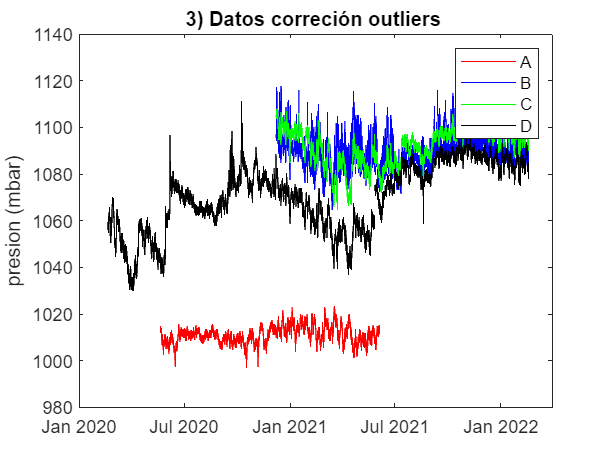

figure()
plot(A.FechaTiempo_GMT_05_00,A.PresAbs_Mbar_LGRS_N_20158088_SENS_N_20158088_,'r')
hold on 
plot(B.FechaTiempo_GMT_06_00,B.PresAbs_Mbar_LGRS_N_20081790_duplicate_duplicate_duplicate_dupl,'b')
hold on 
plot(C.FechaTiempo_GMT_06_00,C.PresAbs_Mbar_LGRS_N_20081791_duplicate_duplicate_duplicate_dupl,'g')
hold on 
plot(D.FechaTiempo_GMT_05_00,D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_,'k')
legend("A","B","C","D")
title("3) Datos correción outliers ")
ylabel("presion (mbar)")

**6) Ahora no interesa tener un itervalor de tiempo  igual para poder hacer la compración entre los sitios. En este caso la grafica N°3 nos ayuda a identificar que hay un intervalo de tiempo de intersección**

Se van cortar la series de tiempo en ese intervalo de interés para esto tomamos una fecha minima y maxima como referencia de cortes 

minf=[2020,12,7,15,0,0];
minf=datetime(minf)

minf = datetime
   07-Dec-2020 15:00:00


maxf=[2021,11,5,08,0,0];
maxf=datetime(maxf)

maxf = datetime
   05-Nov-2021 08:00:00


Cortamos las series de tiempo por los intervalos que definimos

g=isbetween(A.FechaTiempo_GMT_05_00,minf,maxf);
A=A(g,:);
clear g 

g=isbetween(B.FechaTiempo_GMT_06_00,minf,maxf);
B=B(g,:);
clear g

g=isbetween(C.FechaTiempo_GMT_06_00,minf,maxf);
C=C(g,:);
clear g

g=isbetween(B.FechaTiempo_GMT_06_00,minf,maxf);
B=B(g,:);
clear g

g=isbetween(D.FechaTiempo_GMT_05_00,minf,maxf);
D=D(g,:);
clear g 

g=isbetween(patm.FechaTiempo_GMT_05_00,minf,maxf);
patm=patm(g,:);
clear g

Ahora vemos que*** hay NaN*** entonces podemos debemos interpolar para rellenar los huecos en la señal. 

En este caso se puede interpolar sin tanto problema ya que tiene una cantidad baja de puntos faltantes, en caso de tener meses o varias semanas sin datos no se puede hacer una interpolación valida. 

Para hacer la interpolación de los datos vamos a utilizar la función ***fillmissing ***aplicada la columna de datos de interés, en este caso la de nuestros datos de presión. 

La función va a interpolar utilizando la media movil ***movmedian con ventana de 4 datos *** esta metodología de interpolación puede ser cambiada dependiendo de las caracteristicas de la señal. Por ejmplo, usando otro método o cambiando el tamaño de la ventana dentro de las entras de la función. ***Aqui se recomienda visitar la pagina de Matlab ***y buscar las caracteristicas de la función *fillmissing. *

A.PresAbs_Mbar_LGRS_N_20158088_SENS_N_20158088_=fillmissing(A.PresAbs_Mbar_LGRS_N_20158088_SENS_N_20158088_,"movmedian",4);
B.PresAbs_Mbar_LGRS_N_20081790_duplicate_duplicate_duplicate_dupl=fillmissing(B.PresAbs_Mbar_LGRS_N_20081790_duplicate_duplicate_duplicate_dupl,"movmedian",4);
C.PresAbs_Mbar_LGRS_N_20081791_duplicate_duplicate_duplicate_dupl=fillmissing(C.PresAbs_Mbar_LGRS_N_20081791_duplicate_duplicate_duplicate_dupl,"movmedian",4);
D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_=fillmissing(D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_,"movmedian",4);
patm.PresAbs_Mbar_LGRS_N_20081788_SENS_N_20081788_=fillmissing(patm.PresAbs_Mbar_LGRS_N_20081788_SENS_N_20081788_,"movmedian",4);

Vemos que este es el tamaño que debe tener la señal, esto nos ayuda a conocer si nuestra interpolación y cortes son correctos. 

sz=[minf:hours:maxf]';

Ahora vemos que aunque los sensores midieron cada hora, no lo hiceron en horas fijas (13:00,14:00 ...etc) si no que ***hicieron mediciones en otra fecha*** ( P.ejm: 19:27:28, 20:27:28, 21:27:28...etc) Vamos a corregir esto haciendo un ***retime*** de los datos. 

Esto consiste basicamente en hacer una **interpolación** con los datos que se tienen al rededor. En este caso se hace un remuestreo para que sea cada hora (13:00,14:00 ...etc) realizando una interpolación lineal 

Hacer esto es de utilidad ya que los datos del SMN y CONAGUA estan expresadas cada hora (13:00,14:00 ...etc) 

A=  retime(A(:,1:3),'hourly','linear');
C= retime(C(:,1:3),'hourly','linear');
B= retime(B(:,1:3),'hourly','linear');
D= retime(D(:,1:3),'hourly','linear');
patm= retime(patm(:,1:3),'hourly','linear');

Volvemos a visualizar, en este caso van a ser los datos que ya estan corregidos de todos los errores

figure()
    plot(A.FechaTiempo_GMT_05_00,A.PresAbs_Mbar_LGRS_N_20158088_SENS_N_20158088_,'r')
    hold on 
    plot(B.FechaTiempo_GMT_06_00,B.PresAbs_Mbar_LGRS_N_20081790_duplicate_duplicate_duplicate_dupl,'b')
    hold on 
    plot(C.FechaTiempo_GMT_06_00,C.PresAbs_Mbar_LGRS_N_20081791_duplicate_duplicate_duplicate_dupl,'g')
    hold on 
    plot(D.FechaTiempo_GMT_05_00,D.PresAbs_Mbar_LGRS_N_20158088_10000297_duplicate_duplicate_SENS_,'k')
    xlim([minf, maxf])
    ylim([1000, 1130])
title("4) Datos corregidos NA/outliers, interpolado-remuestreo")
legend("A","B","C","D","Patm")

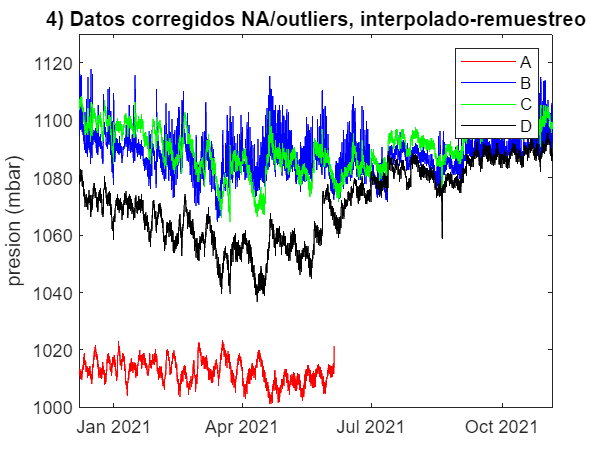

ylabel("presion (mbar)")

#### Restar la presión atmosferica

 Ahora se deben tomar los datos de Patm para restar. No se porque pero en timetable no puedo restar direct, entonces los hago tabla o matriz

%La hacemos matrices 
A=table2array(A(:,2:3));
B=table2array(B(:,2:3));
C=table2array(C(:,2:3));
D=table2array(D(:,2:3));
patm=table2array(patm(:,2:3));

%De ahora en adelante columna 1 es Presion y columna 2 Temperatura 
%Separamos tiempo 

t=sz;
clear sz 

Restamos la patm a los niveles de inundación 

A(:,1)=A(:,1)-patm(1:length(A),1);
C(:,1)=C(:,1)-patm(:,1);
B(:,1)=B(:,1)-patm(:,1);
D(:,1)=D(:,1)-patm(:,1);

%Pasamos los mbar a cm 
h2o=1.01972 % 1mbar en cmH2O

h2o = 1.0197


A(:,1)=A(:,1)*h2o;
B(:,1)=B(:,1)*h2o;
C(:,1)=C(:,1)*h2o;
D(:,1)=D(:,1)*h2o;

%Restamos el nivel de instalación del sensor 
A(:,1)=A(:,1)-45;
B(:,1)=B(:,1)-70;
C(:,1)=C(:,1)-70;
D(:,1)=D(:,1)-80;


Graficamos presión 

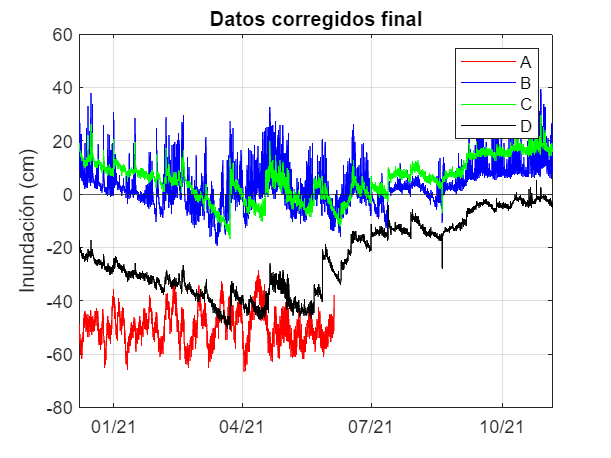

figure()
    plot(t(1:length(A)),A(:,1),'r')
    hold on 
    plot(t,B(:,1),'b')
    hold on 
    plot(t,C(:,1),'g')
    hold on 
    plot(t,D(:,1),'k')
    grid on 
    datetick('x','mm/yy')
    title("Pet")
    xlim([minf, maxf])
    ylabel("Inundación (cm)")
    yline(0,'-')
    title("Datos corregidos final")
    legend("A","B","C","D")

Graficamos temperatura 

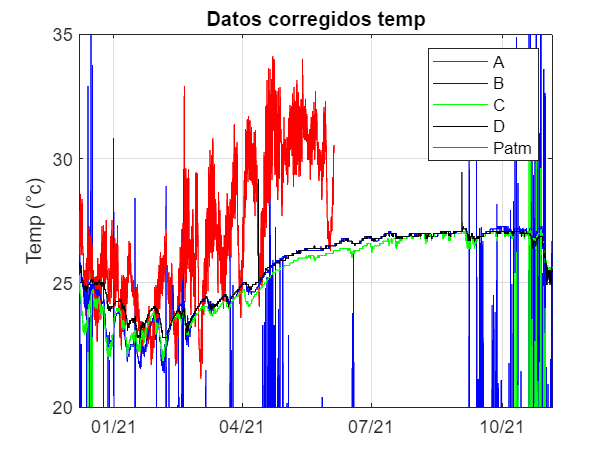

figure(6)
    plot(t(1:length(A)),A(:,2),'r')
    hold on 
    plot(t,B(:,2),'b')
    hold on 
    plot(t,C(:,2),'g')
    hold on 
    plot(t,D(:,2),'k')
    grid on 
    datetick('x','mm/yy')
    title("Pet")
    ylim([20 , 35])
    xlim([minf, maxf])
    ylabel("Temp (°c)")
    yline(0,'--')
    title("Datos corregidos temp")
    legend("A","B","C","D","Patm")

Para poder calcular rapido lo del hp vamos a meter todo en una matriz con fechas en datevec 

time21=datevec(t);
datosAv=[time21(1:length(A),1:6),A(:,1)];
datos=[time21(:,1:6),B(:,1),C(:,1),D(:,1)];

Esto lo podemos guardar y mandar a calcular el HP con el siguiente scrip. Guardamos datos para calcular el HpT

clearvars -except datos datosAv
%writetable(datos,"./datos21.csv")